## Voice Analysis/ Spectrogram 

### A)

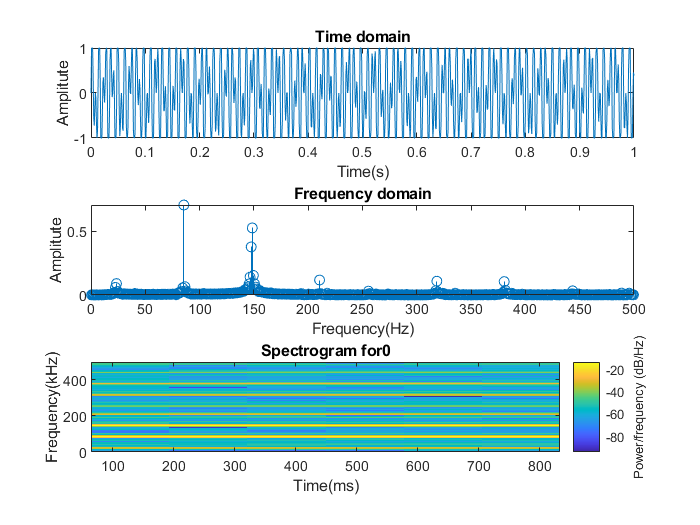

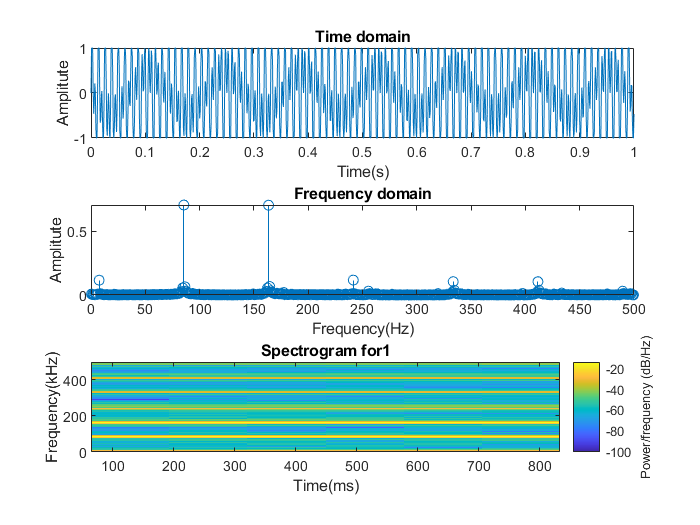

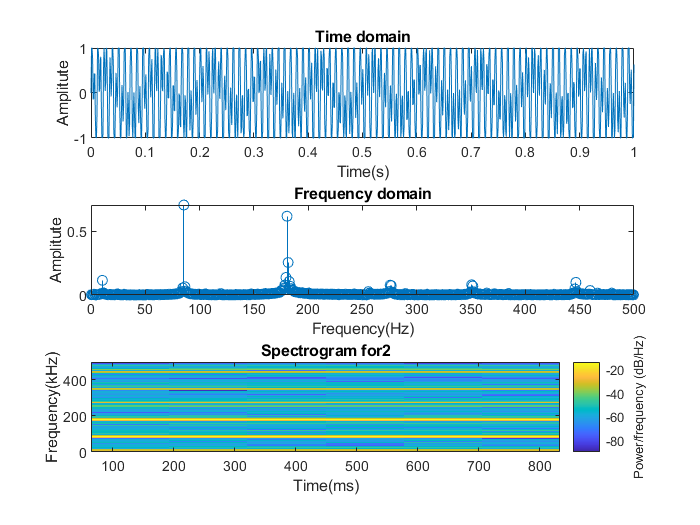

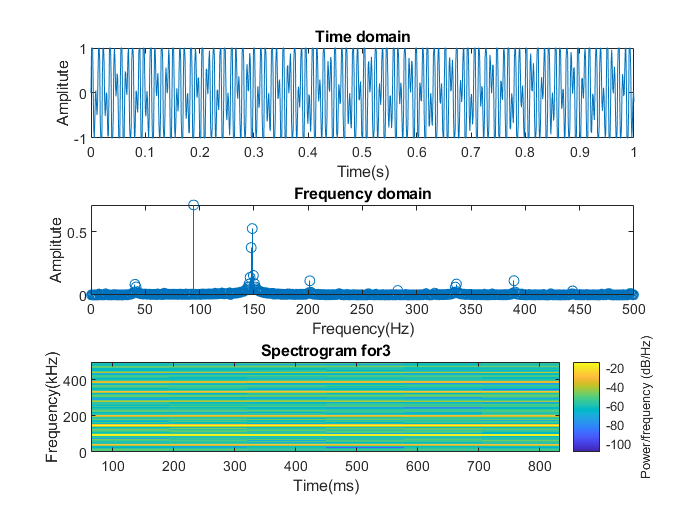

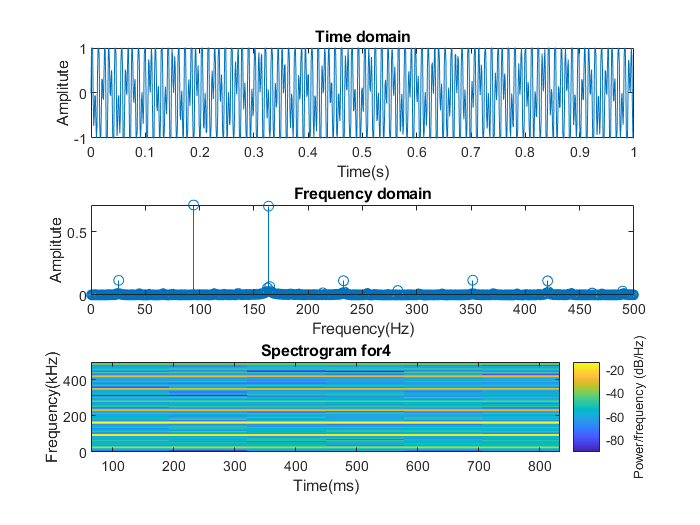

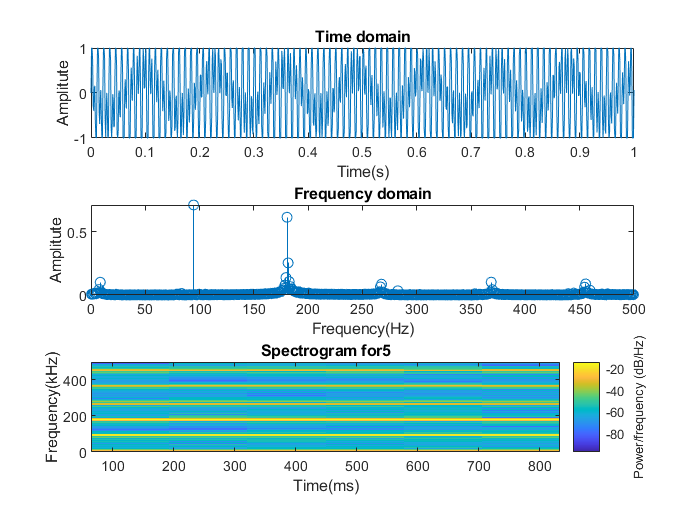

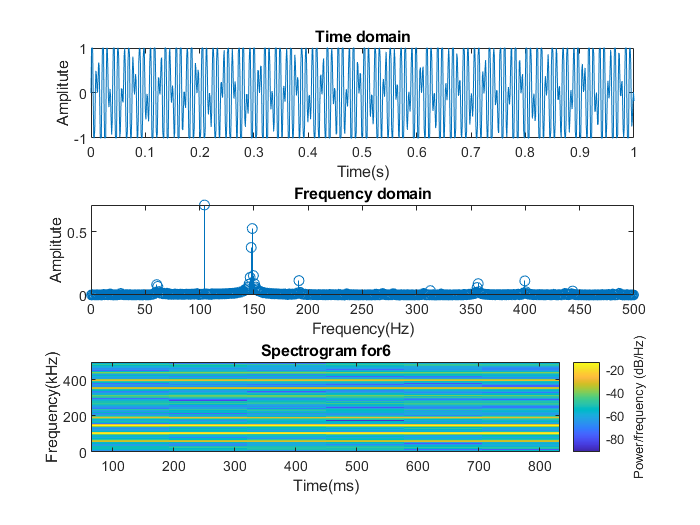

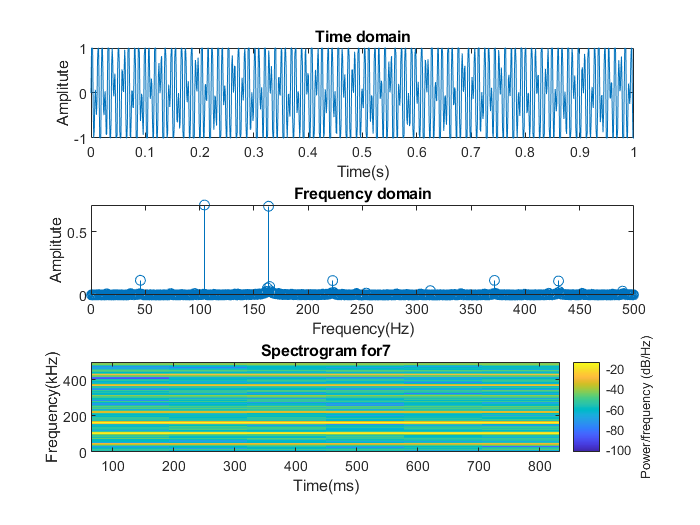

[u1, Fs1] = audioread('voices/key1.wav');
[u2, Fs2] = audioread('voices/key2.wav');
[u3, Fs3] = audioread('voices/key3.wav');
[u4, Fs4] = audioread('voices/key4.wav');
[u5, Fs5] = audioread('voices/key5.wav');
[u6, Fs6] = audioread('voices/key6.wav');
[u7, Fs7] = audioread('voices/key7.wav');
[u8, Fs8] = audioread('voices/key8.wav');
[u9, Fs9] = audioread('voices/key9.wav');
[u0, Fs0] = audioread('voices/key0.wav');
u_values = [(u0), (u1), (u2), (u3), (u4), (u5), (u6), (u7), (u8), (u9)];
Fs_values = [Fs0, Fs1, Fs2, Fs3, Fs4, Fs5, Fs6, Fs7, Fs8, Fs9];

count = 10;
tmin = 0;
tmax = 1;
sampling_rate = (length(u0)-1) / (tmax-tmin);
npts = (tmax-tmin)*sampling_rate + 1;
t_values = tmin:(1/sampling_rate):tmax;
f_values = 1:npts;
tf = (0:npts-1)/npts;

f_shifted_values = linspace(-sampling_rate/2, sampling_rate/2, npts);
U_values = fft(u_values);


for i=(1:count)
    figure
    
    subplot(3,1,1)
    plot(t_values, u_values(:, i))
    title('Time domain')
    xlabel('Time(s)')
    ylabel('Amplitute')
    
    subplot(3,1,2)
    stem(f_shifted_values, 2*fftshift(abs(U_values(:, i)))/sampling_rate)
    title('Frequency domain')
    xlabel('Frequency(Hz)')
    ylabel('Amplitute')    
    xlim([0 500])
    
    subplot(3,1,3)
    spectrogram(u_values(:, i), 256, [], npts, sampling_rate, 'yaxis')
    title(strcat('Spectrogram for ', num2str(i-1)))
    xlabel('Time(ms)')
    ylabel('Frequency(kHz)')
end

### B)

numbers = (0:9).';
largest_f = [85.5, 148.5;85.5, 163.5;85.5, 180.5;94.5, 148.5;94.5, 163.5;94.5, 180.5;104.5, 148.5;104.5, 163.5;104.5, 180.5;115.5, 148.5];
mltable = table(numbers, largest_f(:, 1), largest_f(:, 2))

mltable = 10×3 table
    numbers    Var2     Var3 
    _______    _____    _____

       0        85.5    148.5
       1        85.5    163.5
       2        85.5    180.5
       3        94.5    148.5
       4        94.5    163.5
       5        94.5    180.5
       6       104.5    148.5
       7       104.5    163.5
       8       104.5    180.5
       9       115.5    148.5
